clear
data_tabelle=readtable("Lebensdauer_Bueroklammer.csv");
data=data_tabelle.Zyklen;
%data_tabelle=readtable("viskositaet.xlsx");
%data=data_tabelle.Viskositaet;

%data=randn([20,1])+4;
%data=rand([20,1])+3;
a=1;
%x-Daten, Anzahl Datenwerte etc.
    anzahl=length(data);
    x=(min(data)-a:0.1:max(data)+a);

%Bei allen Optionen ist der Default-Wert das 95% Konfidenzintervall, ändern
%mit z.B. "Alpha",0.01

%Konfidenzintervalle der Parameter von Verteilungen
pd_norm=fitdist(data,'Normal')

pd_norm =   NormalDistribution

  Normal distribution
       mu = 15.6133   [10.6343, 20.5924]
    sigma = 21.6407   [18.6461, 25.7903]


ci_normal=paramci(pd_norm,'Alpha',0.05)

ci_normal =    10.6343   18.6461
   20.5924   25.7903


pd_weibull=fitdist(data,'Weibull')

pd_weibull =   WeibullDistribution

  Weibull distribution
    A =  15.2792   [11.8995, 19.6187]
    B = 0.960767   [0.820185, 1.12545]


ci_weibull=paramci(pd_weibull,'Alpha',0.05)

ci_weibull =    11.8995    0.8202
   19.6187    1.1254


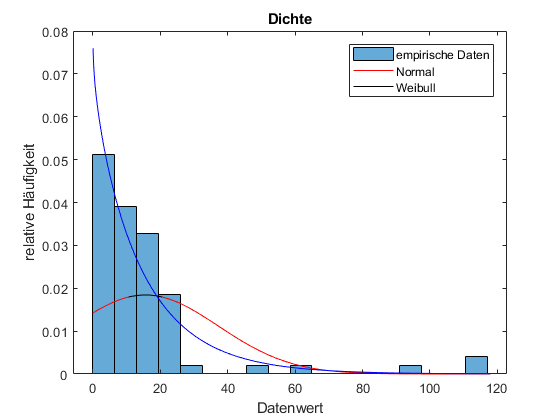


figure(1)
histogram(data,2*round(sqrt(anzahl)),'Normalization','pdf')
hold on
plot(x,normpdf(x, pd_norm.mu,pd_norm.sigma),'Color','r')
plot((ci_normal(1):0.1:ci_normal(2)),normpdf((ci_normal(1):0.1:ci_normal(2)), pd_norm.mu,pd_norm.sigma),"Color","black")
plot(x,wblpdf(x, pd_weibull.A,pd_weibull.B),'Color','b')

title('Dichte')
xlabel('Datenwert')
ylabel('relative Häufigkeit')
legend('empirische Daten', 'Normal','Weibull')
hold off

%Konfidenzintervalle über Tests
%t-Verteilung:
[t_h,t_p,t_ci,t_stats]=ttest(data)

Struct contents reference from a non-struct array object.

%Verteilungsunabhängige Konfidenzintervalle für Quantile
%Berechnung des Konfidenzintervalls für den Median (McGill 1978)
ci_lower=median(data)-1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
ci_upper=median(data)+1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
ci_median=[ci_lower,ci_upper]

%Veranschaulichung der Verteilung incl. Konfidenzintervall vom Median im
%Boxplot (Matlab verwendet obige Formel)
boxplot(data,"Notch","on")
boxplot(data,"Notch","marker")


%Bootstrapping 
[boot_stats, data_boot]=bootstrp(100,@median,data)
figure(4)
histogram(data)
hold on
histogram(data(data_boot))
hold off
ci_boot_mean=bootci(100,{@mean,data})
[ci_boot_median,stats]=bootci(100,{@median,data})


data_chol = readtable('cholesterinsenker.csv')

data_chol = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


[h,p,ad_ci,ad_test] = adtest(data_chol.A,data_chol.B,'Alpha',0.01)

Error using internal.stats.parseArgs (line 42)
Wrong number of arguments.

Error in adtest (line 75)
    internal.stats.parseArgs(paramNames, dflts, varargin{:});